# Intro to Computational Photography (cp) Classes

cpCamera is one of a set of classes that allow experimentation with computational photography more easily and compactly than directly programming the structures they encapsulate (scene, oi, sensor, and ip). Along with cpScene, cpCModule, and cpIP, it provides a programmable wrapper that allows users to create "computational cameras" that have a variety of algorithms for generating scene sequences, deciding how to capture a scene based on a preview, capturing the scene in one or more frames, and then processing those frames into a photo, 

Currently, CPCameras are assumed to have a single camera module with a single sensor, but the architecture is designed to allow expansion to multi-module systems.

History: Initial Version: D. Cardinal 12/2020, iset scene support added 1/2021

#### Block Diagram of "cp" classes

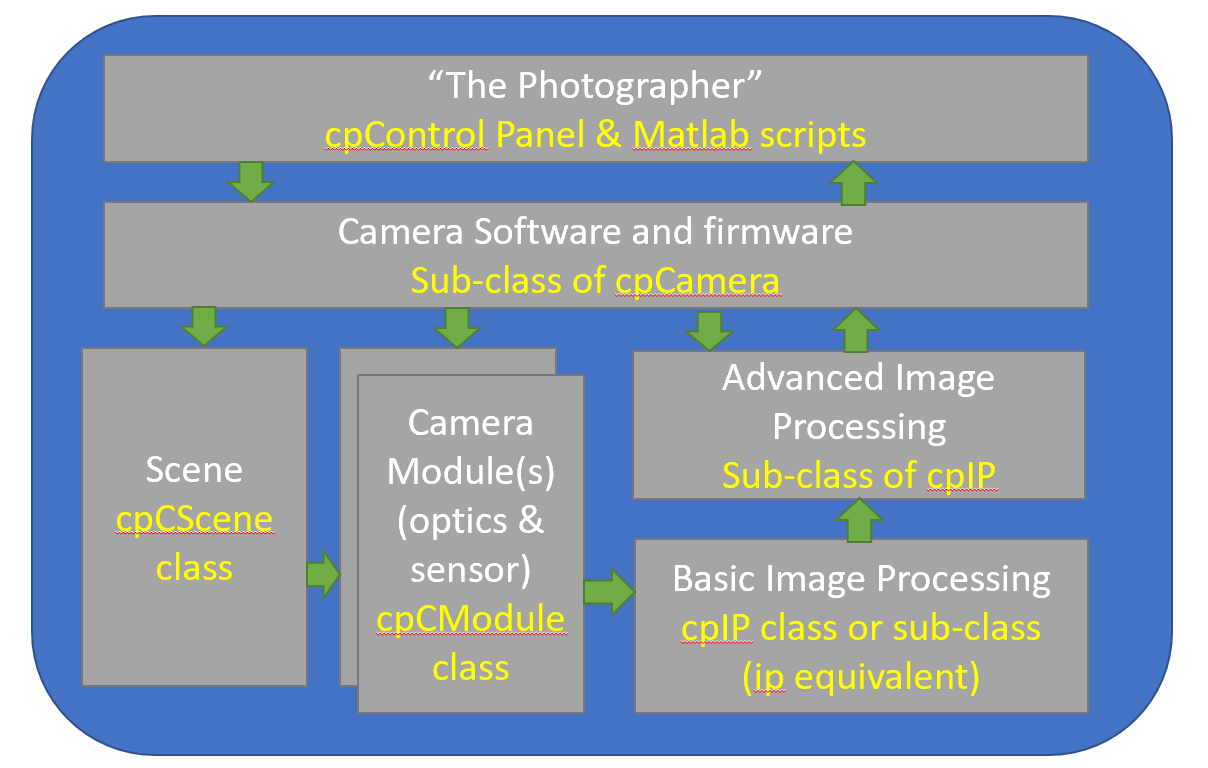

In this tutorial we'll use sub-classes of cpCamera and cpIP that are enhanced to support several different simulation and processing features. cpBurstCamera and cpBurstIP can use a cpScene object to add both camera and object motion to a pbrt scene, or camera motion to ISET scenes or pre-computed images. They can also take a sequence of images that already have motion incorporated.

Once the initial sensor images are created, cpBurstIP can either use existing ISET ip algorithms to do burst and HDR at the raw sensor level, or employ higher-level image registration and tone mapping algorithms on multiple frames. A main goal of the cp classes is to allow students and researchers to use the default implementations as a jumping off point for projects of various kinds.

### Block Diagram of our "Burst" Camera

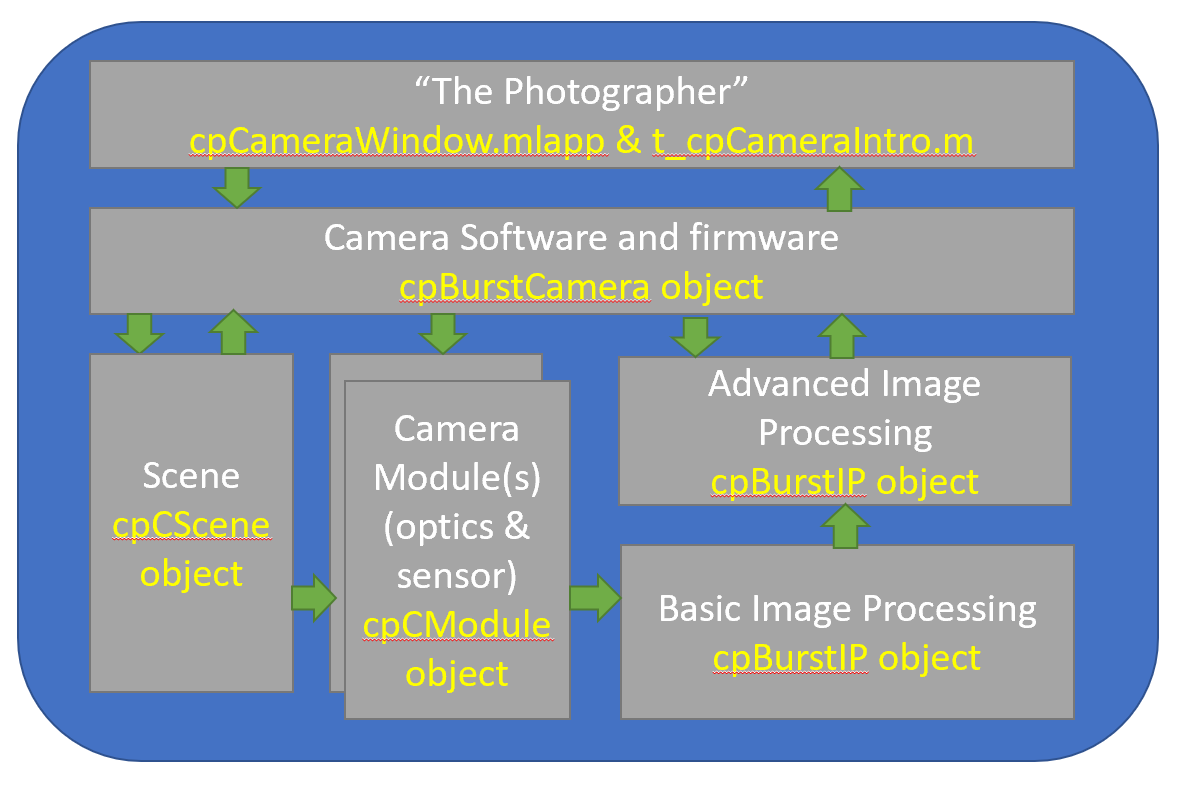

## Initialize our Computational Camera

As a first step we create a camera object based on the cpBurstCamera class, that adds support for simple image registration and tone-mapping to the base cpCamera class. After we create the camera, we equip it with a single camera module, that includes an off-the-shelf sensor and the default optics.

ieInit();
setpref('ISET', 'fast_num2string', true); % use faster piWrite

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Create our Scene

The Cornell Box + Stanford Bunny is part of iset3d, and is set up to help us by labeling the assets in such a way that we can add motion to them as they are rendered by pbrt. You can use the sliders below to control the lighting level (mean luminance) of the rendered scene, as well as the number of rays per pixel pbrt uses and its "film" resolution. We've kept the defaults low to speed up rendering, but for real experiments you may want to increase them:

sceneLuminance = 200

sceneLuminance = 200

numRays = 256

numRays = 256

filmResolution = 256

filmResolution = 256

pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "CornellBoxReference"

sceneChoice = "CornellBoxReference"

apertureDiameter = 6% in mm

apertureDiameter = 6

if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 9 materials.
Read 0 textures.
***Scene parsed.


## Let's Look at the Camera we've Created

cpCameraWindow(ourCamera, pbrtCPScene);

## Set an Object in Motion in our PBRT Scene

We can set any named object in the asset tree of a pbrt scene in motion using by adding values to the .objectMotion array. Here we'll set the Stanford bunny (labeled as "Default_B" in the asset tree) into motion with a vertical movement (middle term of the first triplet) and a tiny rotation (the second triplet). Later we'll show how the camera can also be set in motion:

% Move the bunny up, with slow rotation
if strcmp(sceneName, 'cornell box bunny chart')
    pbrtCPScene.objectMotion = {{'Default_B', [0, 15, 0], [1, 1, 1]}};
end

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.241711 seconds.
*** Rendering time for CornellBoxReference:  10.5 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBox

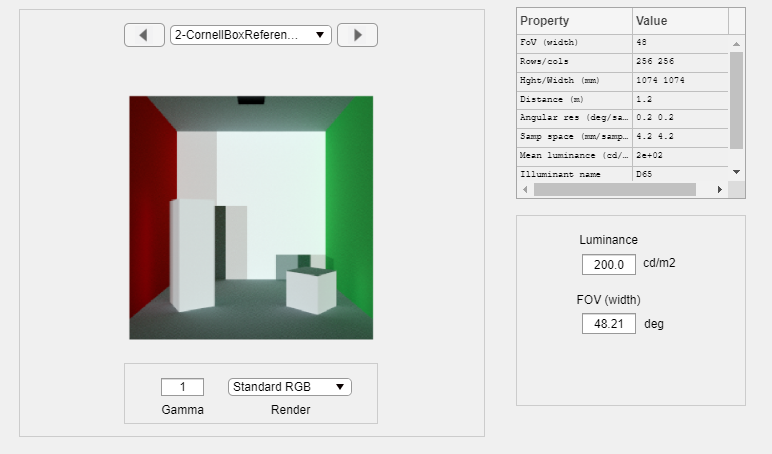

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode'); 

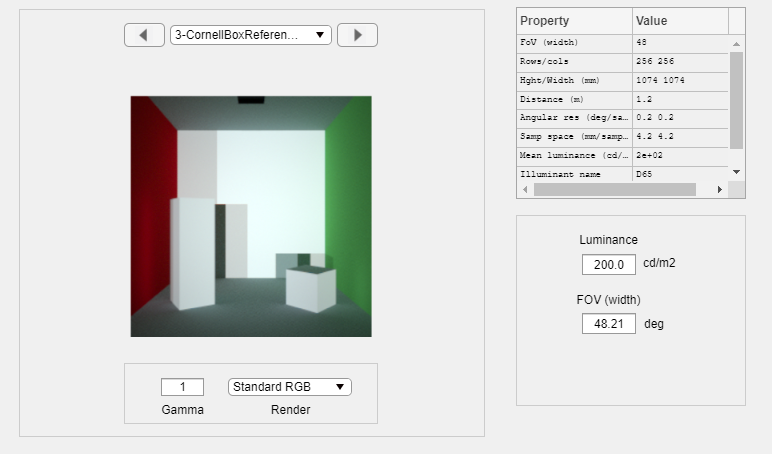

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.7 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.249011 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.3 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.250378 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Elapsed time is 0.246869 seconds.
*** Rendering time for CornellBoxReference:  10.5 sec ***

*** Rendering time for CornellBoxReference_depth:  1.6 sec ***

Elapsed time is 0.248406 seconds.
*** Rendering time for CornellBoxReference:  10.9 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***



imshow(autoImage);

hdrImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR Example', ...
    'insensorIP', true);

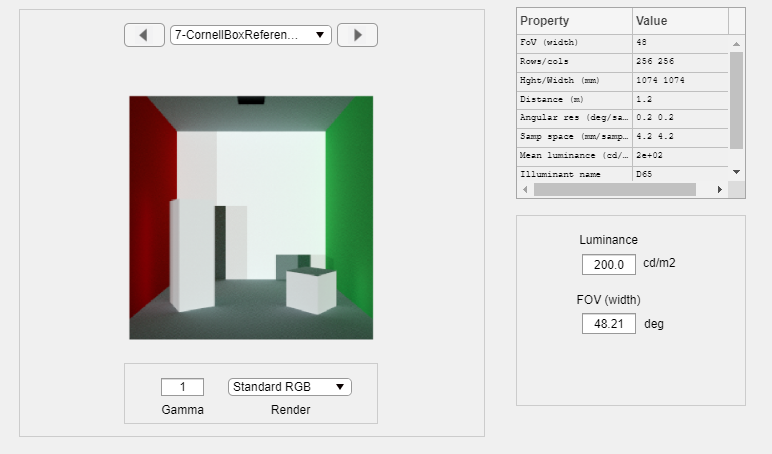

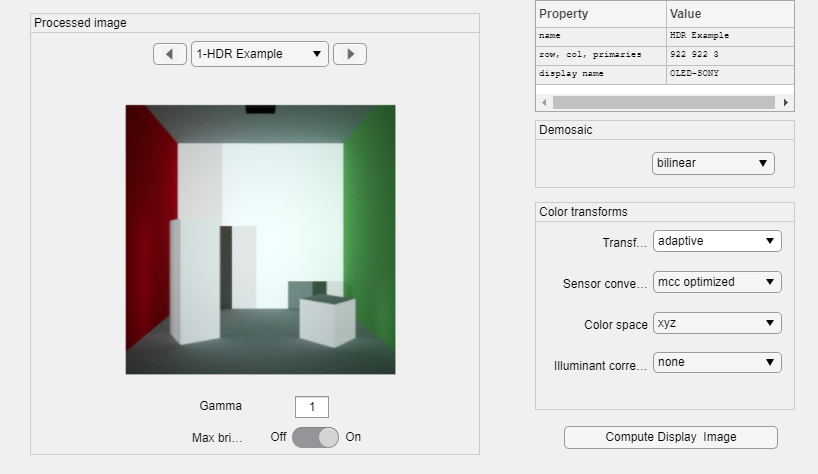

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.257384 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.6 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.258506 seconds.
*** Rendering time for CornellBoxReference:  10.5 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Elapsed time is 0.242095 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Elapsed time is 0.247819 seconds.
*** Rendering time for CornellBoxReference:  10.3 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***



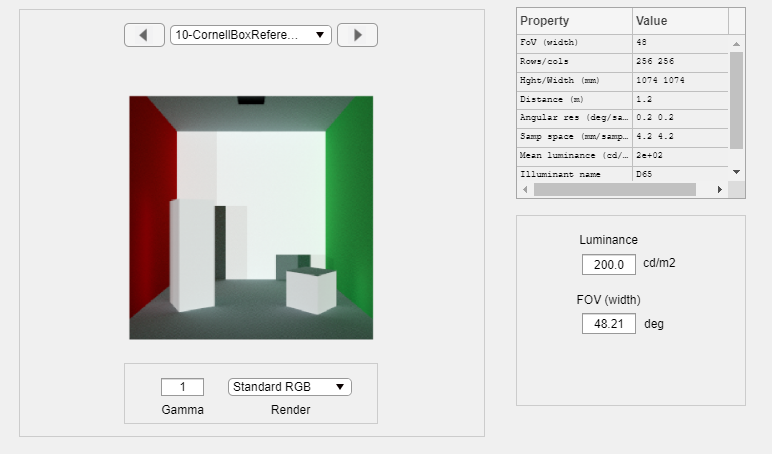

ipWindow(hdrImage);

hdrImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR Example');

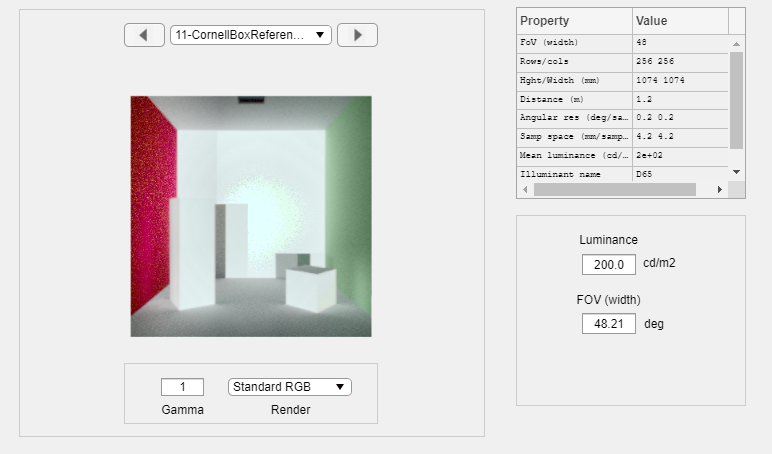

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.247729 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.3 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
Elapsed time is 0.251652 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Elapsed time is 0.248377 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***

Elapsed time is 0.249956 seconds.
*** Rendering time for CornellBoxReference:  10.4 sec ***

*** Rendering time for CornellBoxReference_depth:  1.4 sec ***



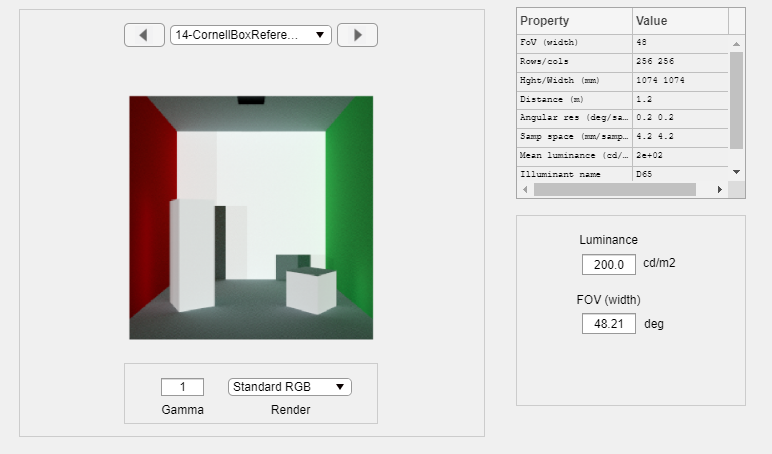

imshow(hdrImage);

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst Example');

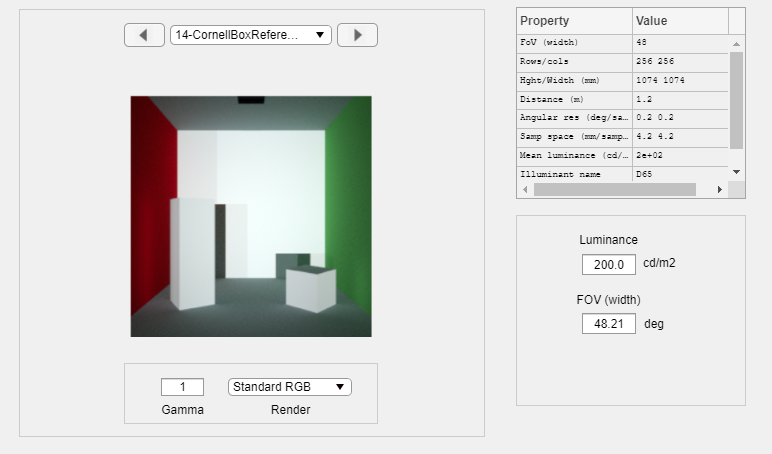

imshow(burstImage);

## Add Some Camera Motion

Note that we don't have a way to move the camera during frames (yet), so it only moves between frames. We also don't have a way to specify multiple cameras yet, so the first parameter is unused:

pbrtCPScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the camera rotating and
% translating slightly, perhaps mimicing a user's hand motion
%finalImage = ourCamera.TakePicture(pbrtCPScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst with Camera Motion');
%imtool(finalImage);


## Look at the changes we've made to our camera

cpCameraWindow(ourCamera, pbrtCPScene);

## Working With ISET Scenes

While to get a fully-simulated 3D scene we need to use PBRT to render a Recipe, we can also take advantage of the variety of ISET Scenes (saved in .MAT files, or already loaded into ISET). Using them we can still emulate camera motion by moving the scene. 

ourSceneFile = fullfile('Feng_Office-hdrs.mat');
isetCIScene = cpScene('iset scene files', 'isetSceneFileNames', ourSceneFile, ...
    'sceneLuminance', sceneLuminance);

Reading multispectral data with mcCOEF.
Saved using svd method


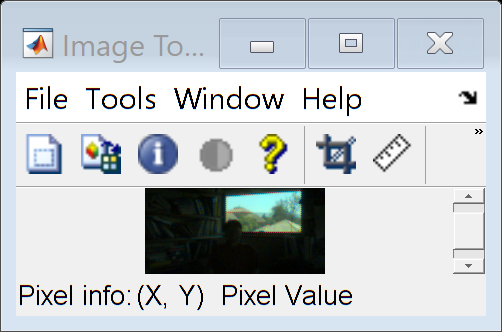


% We can use the same Camera object if we want, but with this new scene.
autoISETImage = ourCamera.TakePicture(isetCIScene, 'Auto',...
    'imageName','ISET Scene in Auto Mode');
imtool(autoISETImage); 

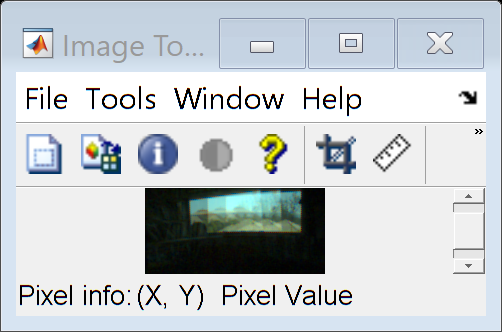


% Set camera motion, which is simulated for iset scenes 
% using scene motion
isetCIScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the the camera (scene) moving
finalImage = ourCamera.TakePicture(isetCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','ISET Burst with Camera Motion');
imtool(finalImage);

##  Working With Image Files

More sophisticated computational imaging algorithms typically rely on large data sets of training and test images. Neither of those exist in pbrt or iset format, so we also support standard RGB image files (.jpg, .png, etc.) We currently don't have a way to simulate object motion for these files, but we do support camera motion through simulating by moving the scene. Here we show an image using default rendering, and then with some camera motion and a burst of images. Note the color artifacts, since the default camera adds photosite values together in the raw sensor, but since the image has shifted, colors aren't correctly aligned:

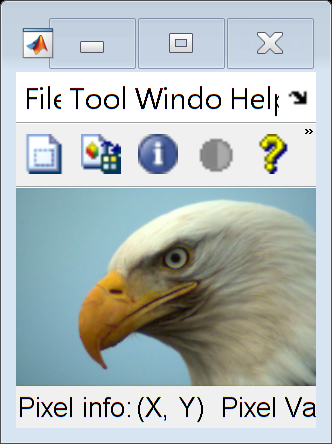

ourImageFile = 'eagle.jpg';
imageCIScene = cpScene('images', 'imageFileNames', ourImageFile);
% We can use the same cpCamera if we want
autoImageCapture = ourCamera.TakePicture(imageCIScene, 'Auto',...
    'imageName','Image File Captured in Auto Mode');
imtool(autoImageCapture); 

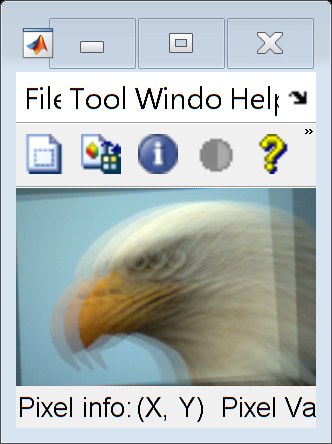


% Set camera motion, which is simulated for iset scenes 
% using scene motion
imageCIScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};

% now see what the burst looks like with the camera (scene) moving
finalImage = ourCamera.TakePicture(imageCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst from Image File with Camera Motion');
imtool(finalImage);

## Using Pre-computed Scene and Object Motion

If we have access to a series of frames that illustrate either camera or object motion, we want to be able to use them directly. A simple example might be a series of frames from a video. To do that we can pass them as an array, either of ISET scenes or simply as image files

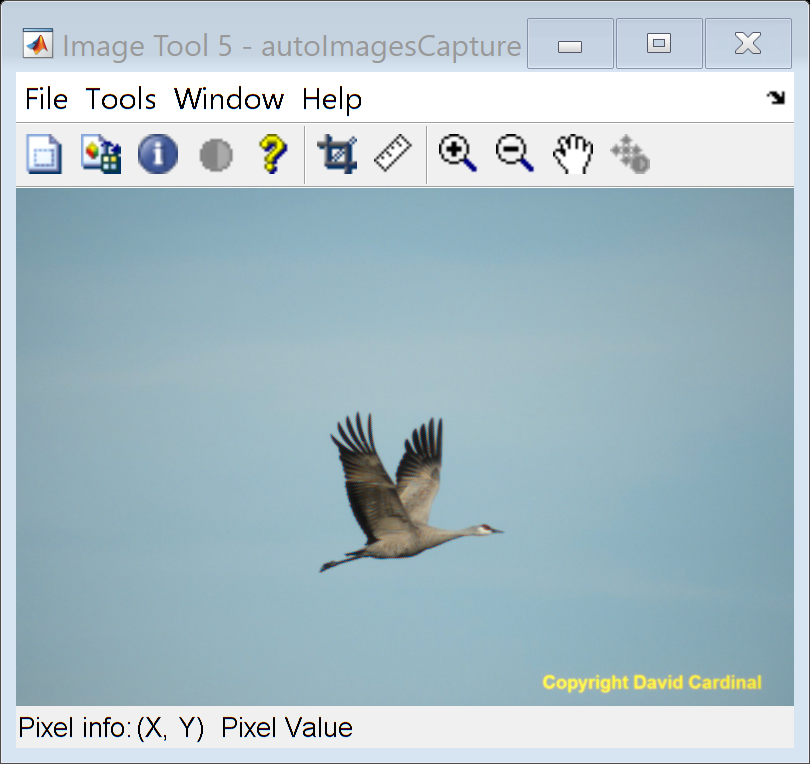

burstImageFiles = {'Crane_01.jpg', 'Crane_02.jpg', 'Crane_03.jpg'};
burstImagesCIScene = cpScene('images', 'imageFileNames', burstImageFiles, ...
   'resolution',[256, 256]);
% We can use the same cpCamera if we want
autoImagesCapture = ourCamera.TakePicture(burstImagesCIScene, 'Auto',...
    'imageName','Sequence of Image Files Captured in Auto Mode');
imtool(autoImagesCapture); 

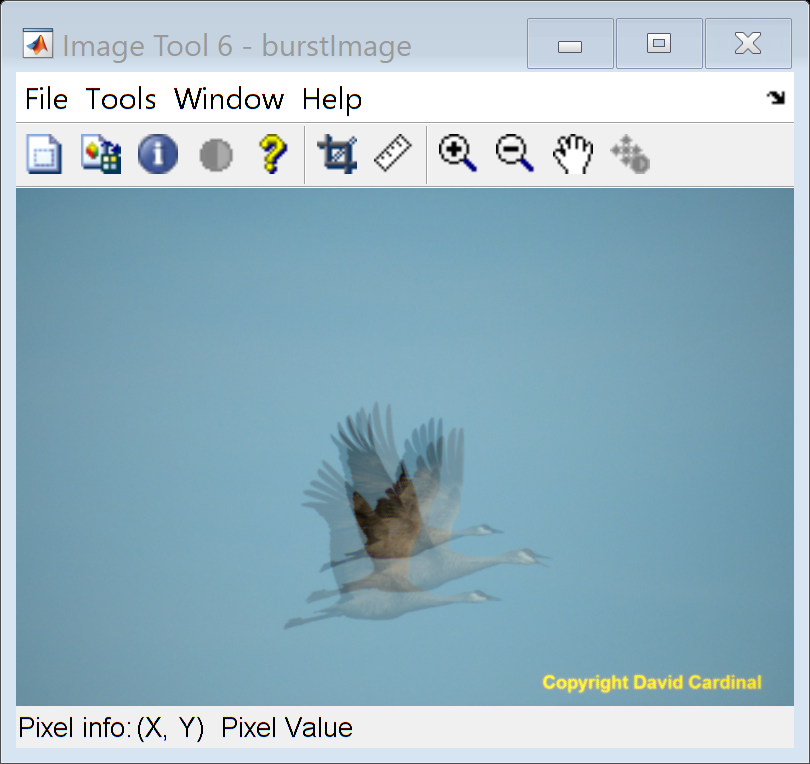


% Note that we can't add our own camera or object motion here, as we are
% simply using pre-computed scenes. Potentially we might want to support
% additional camera motion options, though?

% now see what the burst looks like with the camera (scene) moving
burstImage = ourCamera.TakePicture(burstImagesCIScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst from Image File with Camera Motion');
imtool(burstImage);

## Generate a bracketed sequence from an image

Not sure how useful this is, if the original image is already LDR. But if we get some .exr scenes, we could experiment with those.

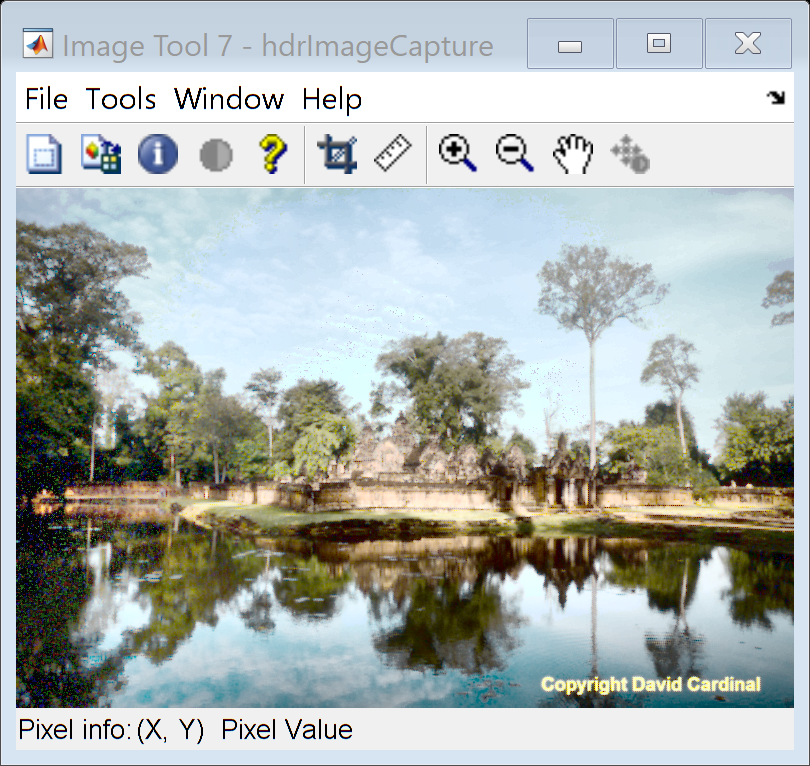

hdrBaseFile = {'BanteaySrei_01.jpg'};
hdrImageCIScene = cpScene('images', 'imageFileNames', hdrBaseFile, ...
   'resolution',[256, 256]);
% We can use the same cpCamera if we want
hdrImageCapture = ourCamera.TakePicture(hdrImageCIScene, 'HDR',...
    'imageName','Sequence of Image Files Captured in HDR Mode');
imtool(hdrImageCapture); 

## Using previously-captured Bracketed (HDR) Photos

We need to decide what to do in this case. The scene has already been captured with specific parameters that differ per frame, so re-capturing gets a bit tricky. Do we use the same exposure times but then "trick" our HDR algorithm by replacing those with the ones from the original photos? Or do something else?

% hdrImageFiles = {'BanteaySrei_01.jpg', 'BanteaySrei_02.jpg', 'BanteaySrei_03.jpg'};
% hdrImagesCIScene = cpScene('images', 'imageFileNames', hdrImageFiles, ...
%    'resolution',[256, 256]);
% % We can use the same cpCamera if we want
% hdrImagesCapture = ourCamera.TakePicture(hdrImagesCIScene, 'HDR',...
%     'imageName','Sequence of Image Files Captured in HDR Mode');
% imtool(hdrImagesCapture); 

## Test Focus Stacking code path

This doesn't work yet, as we have weird sizing issues with lens files, and trying to use depth for the current bunny scene isn't working because sizes are wrong. Need to use the new bunny asset once we figure out how, and have Brian walk us through lens files.

%stackedImage = ourCamera.TakePicture(pbrtCIScene, 'FocusStack',...
%    'imageName','Pretend Stack');
%imtool(stackedImage);

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCam ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCam ran  on: NVIDIA Corporation GeForce RTX 3090/PCIe/SSE2with driver version: 4.6.0 NVIDIA 461.72


disp(strcat("cpCam ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCam ran  in: 457.125 seconds of CPU time.


disp(strcat("cpCam ran  in: ", string(tTotal), " total seconds."));

cpCam ran  in: 288.3034 total seconds.
